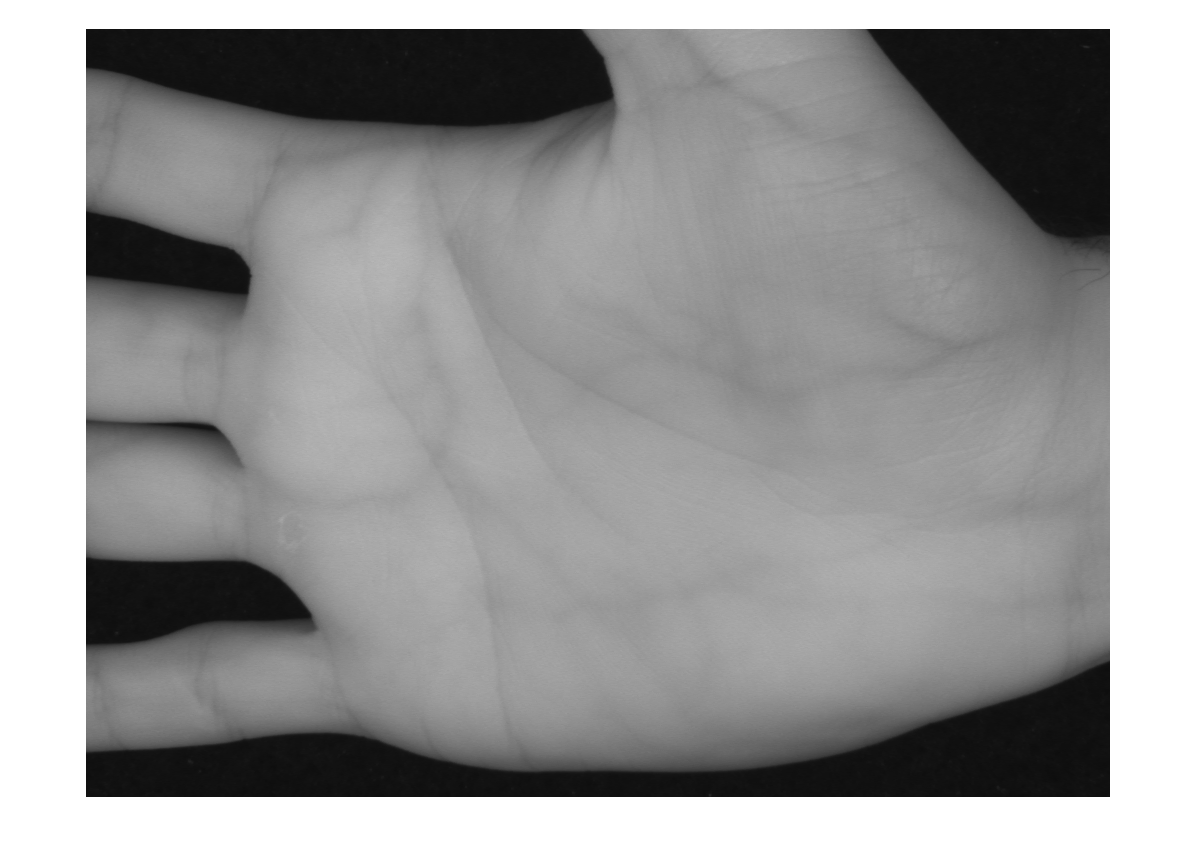

clear; clc;

imagem = imread('..\Dataset\1\08_R_N_L_P.tif');
imshow(imagem)

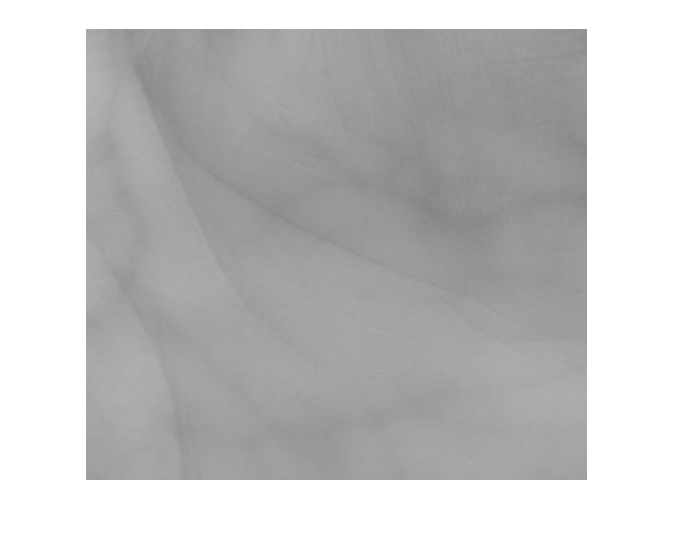

centroid = [size(imagem, 2)/2+50, size(imagem, 1)/2+15];
d1 = 250;
d2 = 225;

E1 = (centroid(2) - d2):(centroid(2) + d2);
E2 = (centroid(1) - d1):(centroid(1) + d1);

ROI = imagem(E1,E2);
imshow(ROI)

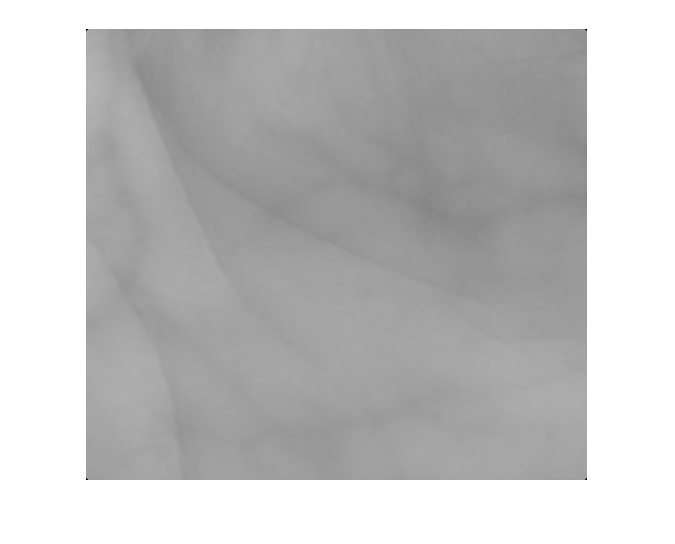

ROI = medfilt2(ROI, [5,5]);
imshow(ROI)

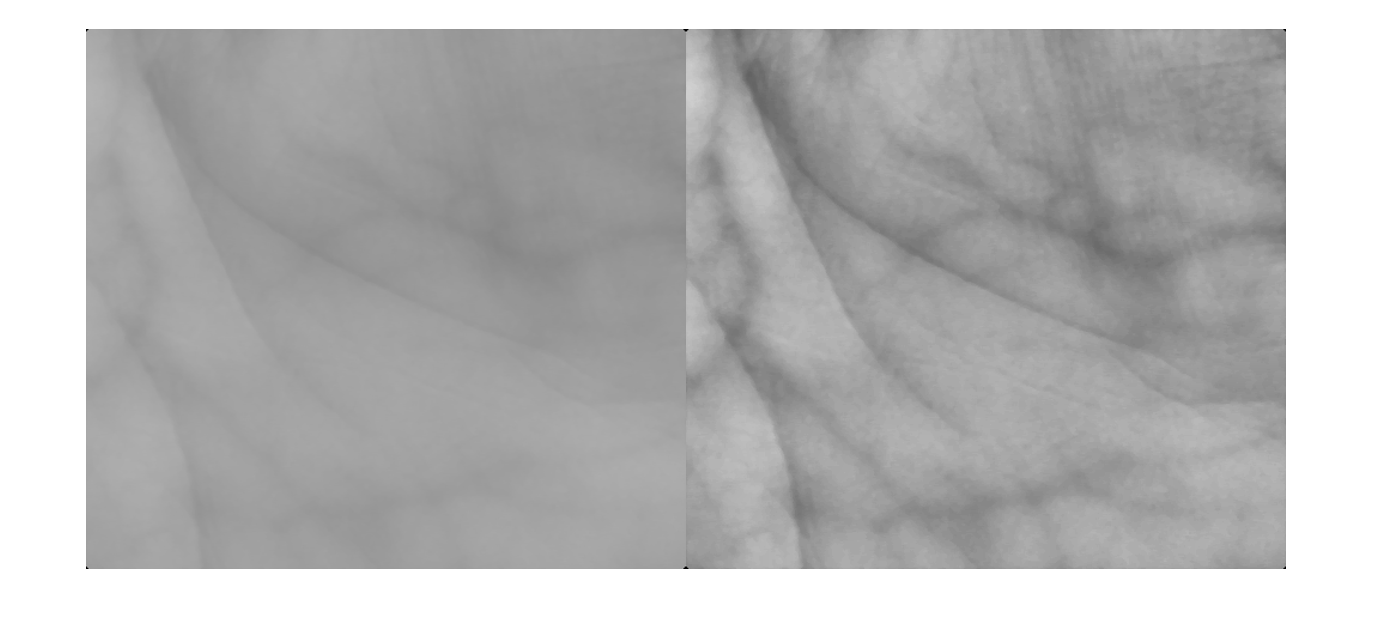

adaptHistEqual = adapthisteq(ROI);
montage({ROI, adaptHistEqual})